# Coding Numerical Sol'ns to ODEs

clear; close all; clc;

% dx/dt = 5*sin(x)
% x0 = pi/4

% x = 2*arctan(exp(5*t)/(1+sqrt(2))

% We will solve from t = 0 to t = 1, dt = 0.1

f = @(x) 5*sin(x);

dt = 0.1;
T = 1;
t = 0:dt:T;

% vector x to hold soln
N = length(t);
x = zeros(1, N);
x(1) = pi/4;

exact = 2*atan(exp(5*t)/(1+sqrt(2)));

## Explicit Euler

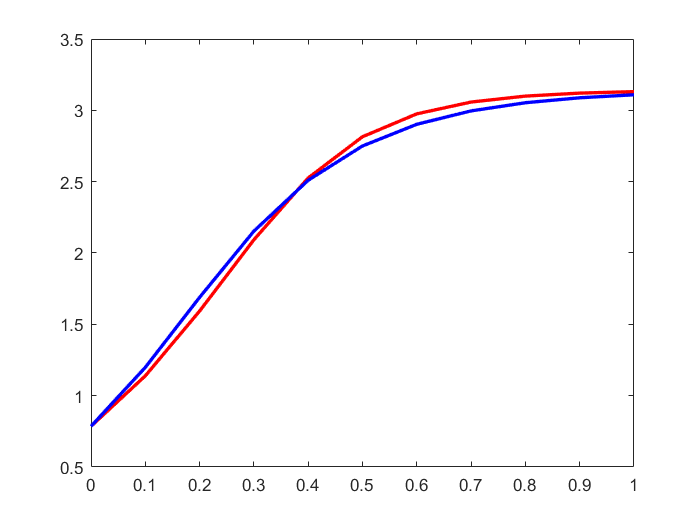

for k = 1:N-1
    x(k+1) = x(k) + dt*f(x(k));
end

figure;
plot(t, x, 'r', 'Linewidth', 2);
hold on;
plot(t, exact, 'b', 'Linewidth', 2);


error = abs(exact(end) - x(end));
disp(error);

    0.0221



## Decrease dt -> 1 Magnitude Lower Error

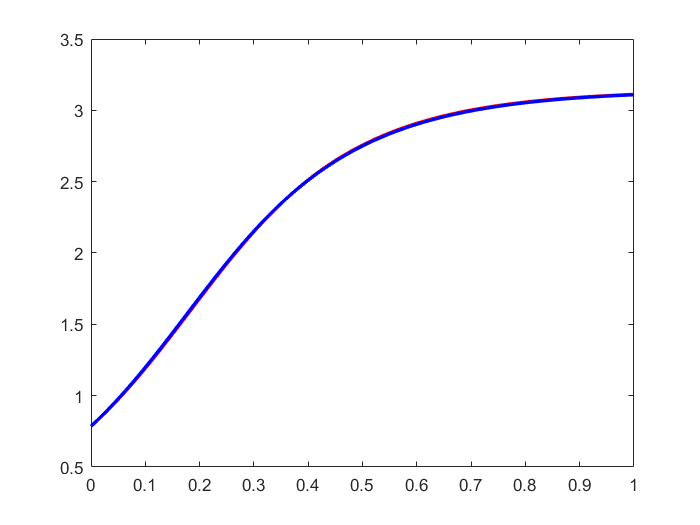

dt = 0.01;
T = 1;
t = 0:dt:T;

% vector x to hold soln
N = length(t);
x = zeros(1, N);
x(1) = pi/4;

exact = 2*atan(exp(5*t)/(1+sqrt(2)));

for k = 1:N-1
    x(k+1) = x(k) + dt*f(x(k));
end

figure;
plot(t, x, 'r', 'Linewidth', 2);
hold on;
plot(t, exact, 'b', 'Linewidth', 2);


error = abs(exact(end) - x(end));
disp(error);

    0.0025



## Implicit Euler

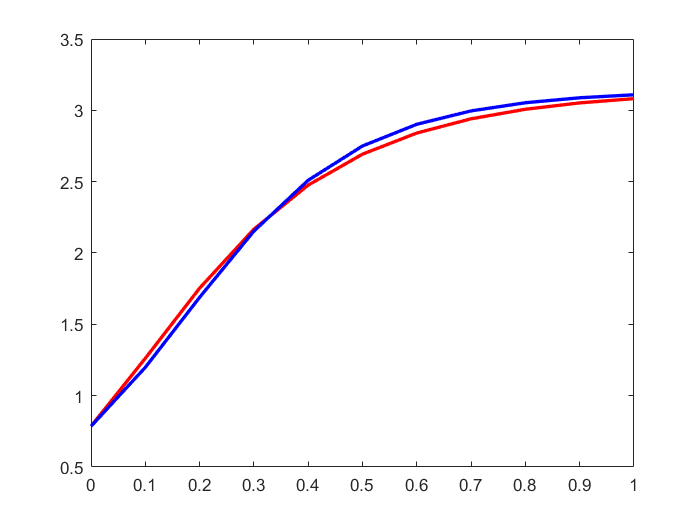

dt = 0.1;
T = 1;
t = 0:dt:T;

% vector x to hold soln
N = length(t);
x = zeros(1, N);
x(1) = pi/4;

exact = 2*atan(exp(5*t)/(1+sqrt(2)));

% x_(k+1) = x_k + dt*f(x_(k+1))
% G(y) = y - x_k - dt*f(y)
% G(x_(k+1)) = 0 -> use fzero
for k = 1:N-1
    g = @(y) y - x(k) - dt*f(y);
    x(k+1) = fzero(g, x(k));
end

figure;
plot(t, x, 'r', 'Linewidth', 2);
hold on;
plot(t, exact, 'b', 'Linewidth', 2);


error = abs(exact(end) - x(end));
disp(error);

    0.0271



## Decrease dt -> 1 Magnitude Lower Error

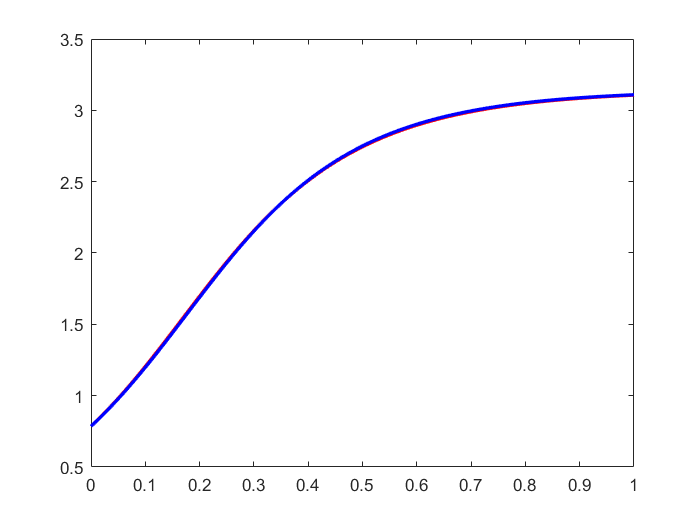

dt = 0.01;
T = 1;
t = 0:dt:T;

% vector x to hold soln
N = length(t);
x = zeros(1, N);
x(1) = pi/4;

exact = 2*atan(exp(5*t)/(1+sqrt(2)));

% x_(k+1) = x_k + dt*f(x_(k+1))
% G(y) = y - x_k - dt*f(y)
% G(x_(k+1)) = 0 -> use fzero
for k = 1:N-1
    g = @(y) y - x(k) - dt*f(y);
    x(k+1) = fzero(g, x(k));
end

figure;
plot(t, x, 'r', 'Linewidth', 2);
hold on;
plot(t, exact, 'b', 'Linewidth', 2);


error = abs(exact(end) - x(end));
disp(error);

    0.0025



## Midpoint Method (RK2)

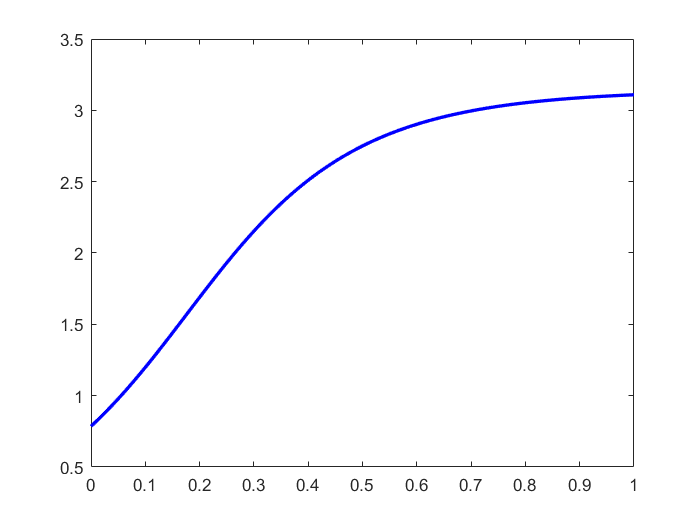

x = zeros(1, N);
x(1) = pi/4;

exact = 2*atan(exp(5*t)/(1+sqrt(2)));

for k = 1:N-1
    k1 = f(x(k));
    k2 = f(x(k) + (dt/2)*k1);
    x(k+1) = x(k) + dt*k2;
end

figure;
plot(t, x, 'r', 'Linewidth', 2);
hold on;
plot(t, exact, 'b', 'Linewidth', 2);


error = abs(exact(end) - x(end));
disp(error);

   4.0272e-05



## RK4

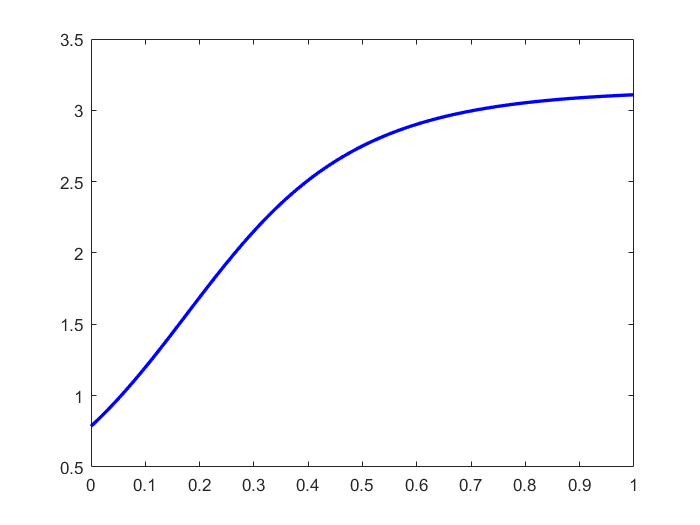

x = zeros(1, N);
x(1) = pi/4;

exact = 2*atan(exp(5*t)/(1+sqrt(2)));

for k = 1:N-1
    k1 = f(x(k));
    k2 = f(x(k) + (dt/2)*k1);
    k3 = f(x(k) + (dt/2)*k2);
    k4 = f(x(k) + dt*k3);
    x(k+1) = x(k) + (dt/6)*(k1 + 2*k2 + 2*k3 + k4);
end

figure;
plot(t, x, 'r', 'Linewidth', 2);
hold on;
plot(t, exact, 'b', 'Linewidth', 2);


error = abs(exact(end) - x(end));
disp(error);

   6.6752e-09



## ode45 - Built-in ODE Solver in MATLAB

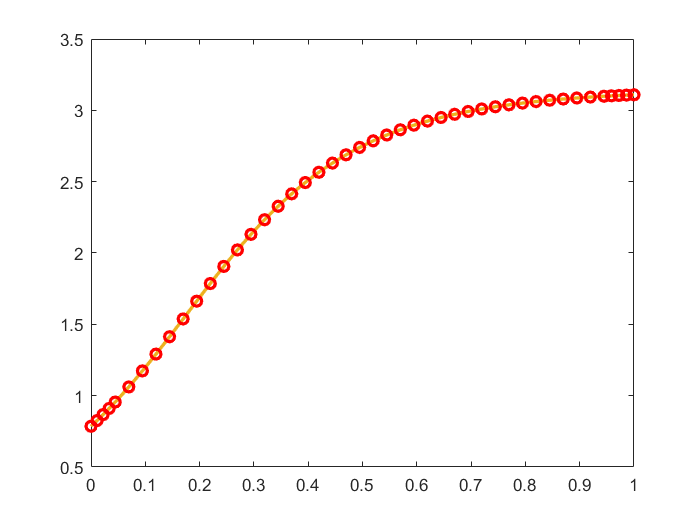

% ode45 - solve the ODE twice
% First pass - RK4
% Second pass - RK5
% If abs(RK5 - RK4) is too high, ode45 will
% decrease timestep and solve again.

% Syntax: [T, X] = ode45(odefun, tspan, x0)

f = @(t, x) 5*sin(x);

[tsol, xsol] = ode45(f, [0 1], pi/4);

exact = 2*atan(exp(5*t)/(1+sqrt(2)));
plot(t, exact, 'linewidth', 2);
hold on;
plot(tsol, xsol, 'ro', 'linewidth', 2);
hold off;


error = abs(exact(end) - xsol(end));
disp(error);

   9.5192e-07



## Systems of ODEs using ode45

% Predator-prey system
% x(t) = population of rabbits
% y(t) = population of foxes

% dx/dt = ax - bxy
% dy/dt = -cy + dxy

a = 4;
b = 2;
c = 1;
d = 2;

% Use ICs x(0) = 1, y(0) = 1.
% Solve for t = 0 to t = 12.

dxdt = @(x, y) a*x - b*x.*y;
dydt = @(x, y) -c*y + d*x.*y;

odefun = @(t, v) [dxdt(v(1), v(2));
                    dydt(v(1), v(2)) ];

v0 = [1; 1];
tspan = linspace(0, 12, 1000);

% Solve using ode45
[tsol, vsol] = ode45(odefun, tspan, v0);

% Create a phase portrait
figure;
x_space = linspace(0, 2, 21);
y_space = linspace(0, 4, 21);
[x, y] = meshgrid(x_space, y_space);
quiver(x, y, dxdt(x,y), dydt(x, y));
hold on;
% Plot a particular trajectory
plot(vsol(:, 1), vsol(:, 2), 'r', 'linewidth', 2);
plot(vsol(1, 1), vsol(1, 2), 'or', 'markersize', 12,...
    'MarkerFaceColor', 'r');
xlabel('Rabbits', 'FontSize', 20);
ylabel('Foxes', 'FontSize', 20);

v0 = [1; 1.5];
[tsol, vsol] = ode45(odefun, tspan, v0);
plot(vsol(:, 1), vsol(:, 2), 'b', 'linewidth', 2)'

ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1000 double]
              YData: [1×1000 double]
              ZData: [1×0 double]

  Show all properties


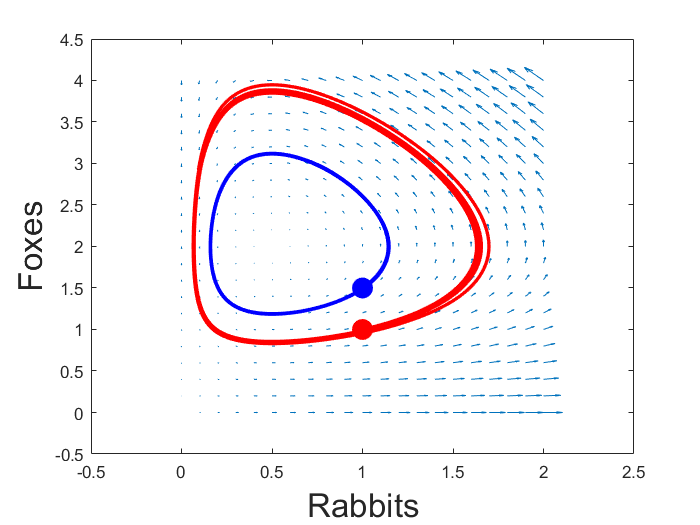

plot(vsol(1, 1), vsol(1, 2), 'ob', 'markersize', 12,...
    'markerfacecolor', 'b');

## Competing Species - Solve using ode45

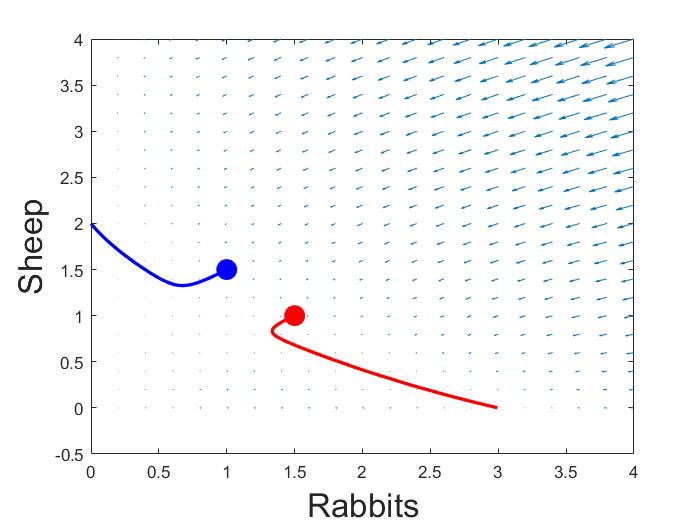

% x(t) = pop of rabbits
% y(t) = pop of sheep

% dx/dt = x*(3-x) - 2*x*y
% dy/dt = y*(2-y) - x*y

dxdt = @(x, y) x.*(3-x) - 2*x.*y;
dydt = @(x, y) y*(2-y) - x.*y;

odefun = @(t, v) [dxdt(v(1), v(2));
                    dydt(v(1), v(2)) ];

v0 = [1.5;1];
tspan = linspace(0, 10, 1000);

[tsol, vsol] = ode45(odefun, tspan, v0);

% Create a phase portrait
figure;
x_space = linspace(0, 4, 21);
y_space = linspace(0, 4, 21);
[x, y] = meshgrid(x_space, y_space);
quiver(x, y, dxdt(x,y), dydt(x, y));
hold on;
% Plot a particular trajectory
plot(vsol(:, 1), vsol(:, 2), 'r', 'linewidth', 2);
plot(vsol(1, 1), vsol(1, 2), 'or', 'markersize', 12,...
    'MarkerFaceColor', 'r');
xlabel('Rabbits', 'FontSize', 20);
ylabel('Sheep', 'FontSize', 20);

v0 = [1;1.5];
[tsol, vsol] = ode45(odefun, tspan, v0);
plot(vsol(:, 1), vsol(:, 2), 'b', 'linewidth', 2);
plot(vsol(1, 1), vsol(1, 2), 'ob', 'markersize', 12,...
    'MarkerFaceColor', 'b');

## Quiz Scratchwork

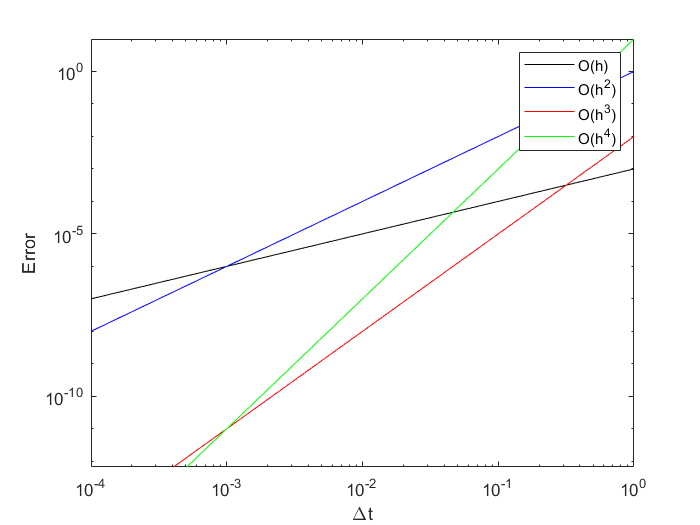

clear; close all; clc;

hs = linspace(10^-4, 10^0);
loglog(hs, 0.001*hs, 'k-');
hold on;
plot(hs, 1*hs.^2, 'b-');
plot(hs, 0.01*hs.^3, 'r-');
plot(hs, 10*hs.^4, 'g-');

legend('O(h)', 'O(h^2)', 'O(h^3)', 'O(h^4)');

xlim([1e-3 1]);
ylim([1e-8 10]);
xlabel('\Deltat');
ylabel('Error');